# PORTAFOLIO SEMANA 1

En este livescript se resulven algunos ejemplos de diagramas de bloques planteados en el libro de Nise para probar las funciones nativas de Matlab para la la resolución de álgebra de bloques, graficación básica en control, (ceros, polos, bode, entre otros)

v

## Día 1

Ejercicio de ejemplo número:

% loques
G1 = tf(1); G1.Name = 'G1';
G2 = tf(1); G2.Name = 'G2';
G3 = tf(1); G3.Name = 'G3';
H1 = tf(1); H1.Name = 'H1';
H2 = tf(1); H2.Name = 'H2';
H3 = tf(1); H3.Name = 'H3';

% Entradas y Salidas
G1.InputName = 'R'; % Cambiado de R(s) a R para evitar errores
G1.OutputName = 'B';
G2.InputName = 'E';       
G2.OutputName = 'F';
G3.InputName = 'F';
G3.OutputName = 'G';
H1.InputName = 'G';
H1.OutputName = 'Z';
H2.InputName = 'G';
H2.OutputName = 'Y';
H3.InputName = 'G';
H3.OutputName = 'X';

% Sumadores
Sum1 = sumblk('C = B - X');
Sum2 = sumblk('D = C + Y');
Sum3 = sumblk('E = D + Z');

% Conexión final
Plant_1 = connect(G1,G2,G3,H1,H2,H3,Sum1,Sum2,Sum3, 'R', 'G');

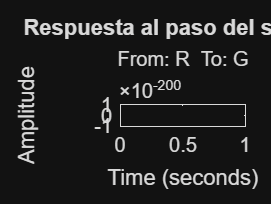


% Ver respuesta
figure;
step(Plant_1);
title("Respuesta al paso del sistema");

Como puede ver, no obtenemos gráfica alguna, dado que no hay dinpámica alguna en nuestro sistema debido a la carencia del factor "s" en los bloques del sistemas.

Reemplazando los bloques del sistema por funciones de transferencia hipotéticas:

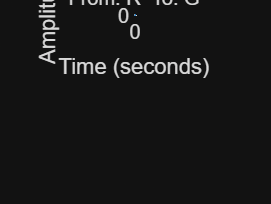

s = tf('s');

% Definimos funciones de transferencia reales (ejemplos)
G1 = 1/(s + 1); G1.Name = 'G1';
G2 = 10/(s^2 + 2*s + 5); G2.Name = 'G2';
G3 = (s + 2)/(s + 8); G3.Name = 'G3';
H1 = tf(1); H1.Name = 'H1'; % Las realimentaciones pueden ser constantes
H2 = tf(0.5); H2.Name = 'H2';
H3 = tf(1); H3.Name = 'H3';

% Entradas y Salidas
G1.InputName = 'R'; % Cambiado de R(s) a R para evitar errores
G1.OutputName = 'B';
G2.InputName = 'E';       
G2.OutputName = 'F';
G3.InputName = 'F';
G3.OutputName = 'G';
H1.InputName = 'G';
H1.OutputName = 'Z';
H2.InputName = 'G';
H2.OutputName = 'Y';
H3.InputName = 'G';
H3.OutputName = 'X';

% Sumadores
Sum1 = sumblk('C = B - X');
Sum2 = sumblk('D = C + Y');
Sum3 = sumblk('E = D + Z');

% Conexión final
Plant_1 = connect(G1,G2,G3,H1,H2,H3,Sum1,Sum2,Sum3, 'R', 'G');

% Ver respuesta
figure;
subplot(2,2,1);
step(Plant_1);
title("Respuesta al paso con dinámica introducida al sistema")
subplot(2,2,1);

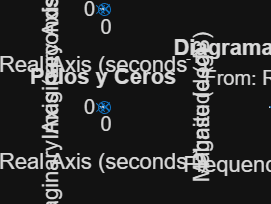

pzmap(Plant_1);
title("Polos y ceros del sistema");
subplot(2,2,3);
pzmap(Plant_1);
title("Polos y Ceros");
subplot(2,2,4);
bode(Plant_1);
title("Diagrama de Bode");

Segundo ejercicio

G1_2 = tf(1/2); 




G1_2.InputName ="A";
G1_2.OutputName = "B";


Tercer ejercicio

% Sistema de presión de pozo (Oil & Gas context)
G = tf([5], [2 1 0]);       % K=5, tau=2s, integrador
H = tf(1, 1);               % Sensor ideal

G_cl = feedback(G, H);     % Lazo cerrado
figure;
subplot(2,2,1); step(G_cl);      title('Step response')
subplot(2,2,2); pzmap(G_cl);     title('Poles & zeros')
subplot(2,2,3); impulse(G_cl);   title('Impulse response')
subplot(2,2,4); bode(G);         title('Open loop Bode')

saveas(gcf, 'day1_analysis.png')
close;

**DIA 2**

Actividad 1

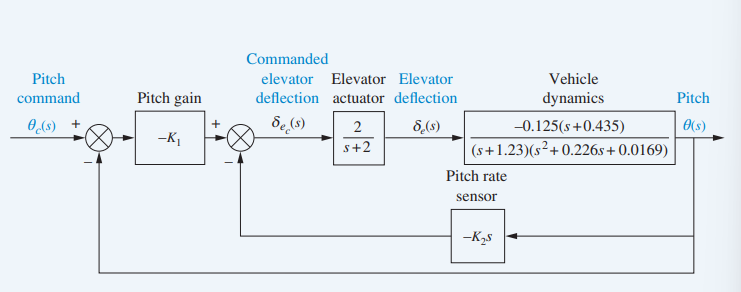

num = 0.125*0.435;
numerador_tetha = tf([-0.125 num]);
denominador_deflection = tf([1 0.226 0.0169])


denominador_deflection =
 
  From input 1 to output:
  1
 
  From input 2 to output:
  0.226
 
  From input 3 to output:
  0.0169
 
Static gain.


sys_1 = tf([-0.125 -num],conv([1, 1.23], [1, 0.226, 0.0169]))


sys_1 =
 
           -0.125 s - 0.05437
  ------------------------------------
  s^3 + 1.456 s^2 + 0.2949 s + 0.02079
 
Continuous-time transfer function.


sys_2_base = tf([0.0169],[1 0.226 0.0169]);
sys_2 = sys_2_base * dcgain(sys_1) %Esto se hace dado que la respuesta cambiará por la aproximación


sys_2 =
 
         -0.04421
  ----------------------
  s^2 + 0.226 s + 0.0169
 
Continuous-time transfer function.


%Esto permite que ambas respuestas sean comparables.
%Inciso a
%Using only the second-order poles shown in the transfer function, predict percent
%overshoot, rise time, peak time, and settling time.
%Percent Overshoot
natural_frequency = sqrt(0.0169)

natural_frequency = 0.1300

syms x
second_order_equation = 2*natural_frequency*x == 0.226;
amortiguation_coefficent = 0.226 / (2 * natural_frequency)

amortiguation_coefficent = 0.8692

percentage_overshoot = (exp(-(amortiguation_coefficent*pi)/sqrt(1- (amortiguation_coefficent)^2)))*100

percentage_overshoot = 0.3993

natural_frequency_damped = natural_frequency*sqrt(1- (amortiguation_coefficent)^2)

natural_frequency_damped = 0.0643

beta = atan(sqrt(1-(amortiguation_coefficent)^2)/amortiguation_coefficent)

beta = 0.5172

rise_time = (pi - beta)/(natural_frequency_damped) 

rise_time = 40.8328

peak_time = (pi)/(natural_frequency_damped)

peak_time = 48.8790

settling_time = (4)/(amortiguation_coefficent * natural_frequency)

settling_time = 35.3982

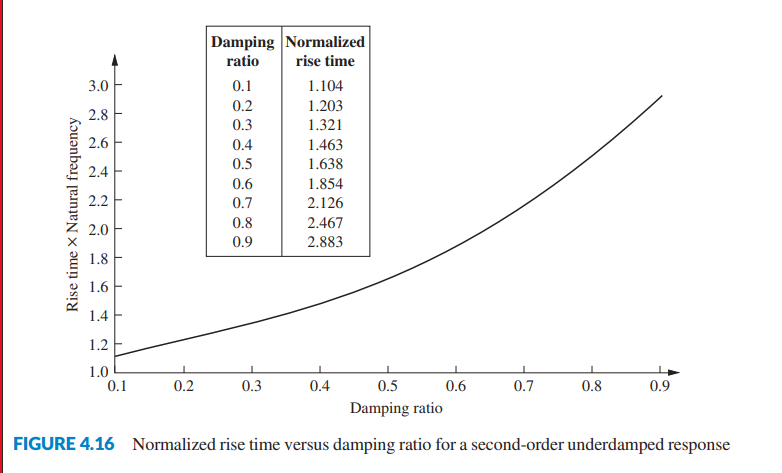

Nótese que el numerador del sistema, tiene un cero en el semiplano derecho (cero positivo). Las ecuaciones de Nise asumen un sistema de segundo orden puro, sin ceros. Esto alterará el comportamiento real del sistema, sobre todo en el percentage overshoot y el rise time. Ahora verifcaremos estos cálculos analíticos mediante la simulación.

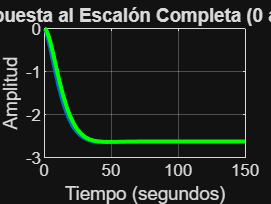

info_real = stepinfo(sys_1);
t_largo = 0:0.1:150;
[y, t] = step(sys_1,t_largo);
info_real_2 = stepinfo(sys_2);
[y_2, t_2] = step(sys_2,t_largo);
figure; 
plot(t, y, 'LineWidth', 2, 'Color', [0 0.4470 0.7410]);
hold on;
plot(t_2, y_2, 'LineWidth', 2, 'Color', [0 1 0]);
title('Respuesta al Escalón Completa (0 a 150s)');
xlabel('Tiempo (segundos)');
ylabel('Amplitud');
grid on;
hold off;

%rlocfind(sys); Solo sirve cuando se está buscando root locus
%hold on;
%grid on;


Se puede notar que los ceros en el plano derecho tienen una gran influencia dentro de la respuesta del sistema. Considerando un sistema de segundo orden puro en base a los polos del sistema, se nota uqe la respuesta en estado estacionario es mucho menor a la respuesta que se obtiene al considerar el sistema completo.

%Inciso B
% Using Laplace transforms, find the analytical expression for the response of the pitch
%angle to a step input in elevator surface deflection.


%Como debemos trabajr en el dominio del tiempo
%Es necesario el uso de variables simbólicas
%Definimos una variable simbólica
clear s; syms s
tetha_s = (-1/s) * (-0.125*(s+0.435)/((s+1.23)*(s^2 + 0.226*s + 0.0169)))

$$tetha\_s = \frac{\frac{s}{8}+\frac{87}{1600}}{s\,\left(s+\frac{123}{100}\right)\,\left(s^{2}+\frac{113\,s}{500}+\frac{169}{10000}\right)}$$

syms t %Creamos la variable simbólica para el tiempo
theta_t = ilaplace(tetha_s,s,t)

$$theta\_t = \frac{165625\,{\mathrm{e}}^{-\frac{123\,t}{100}}}{2566231}-\frac{28352500\,{\mathrm{e}}^{-\frac{113\,t}{1000}}\,\left(\cos\left(\frac{9\,\sqrt{51}\,t}{1000}\right)+\frac{1891291\,\sqrt{51}\,\sin\left(\frac{9\,\sqrt{51}\,t}{1000}\right)}{10411038}\right)}{10577879}+\frac{18125}{6929}$$

theta_t_simplified = simplify(theta_t)

$$theta\_t\_simplified = \frac{165625\,{\mathrm{e}}^{-\frac{123\,t}{100}}}{2566231}-\frac{28352500\,{\mathrm{e}}^{-\frac{113\,t}{1000}}\,\left(\cos\left(\frac{9\,\sqrt{51}\,t}{1000}\right)+\frac{1891291\,\sqrt{51}\,\sin\left(\frac{9\,\sqrt{51}\,t}{1000}\right)}{10411038}\right)}{10577879}+\frac{18125}{6929}$$

%Esta simplificación aún no está en decimales, lo que no la hace tan
%legible
%Para ello usamos vpa()
theta_t_decimal = vpa(theta_t_simplified,4)

$$theta\_t\_decimal = 0.06454\,{\mathrm{e}}^{-1.23\,t}-2.68\,{\mathrm{e}}^{-0.113\,t}\,\left(\cos\left(0.06427\,t\right)+1.297\,\sin\left(0.06427\,t\right)\right)+2.616$$

pretty(theta_t_decimal)

$$0.06454\,{\mathrm{e}}^{-1.23\,t}-2.68\,{\mathrm{e}}^{-0.113\,t}\,\left(\cos\left(0.06427\,t\right)+1.297\,\sin\left(0.06427\,t\right)\right)+2.616$$

 El valor estacionario está dado por 2.61, que sería la posición final en la que se estabilizará el ángulo de cabeceo tras el transitorio. Por otro lado, el término e^-1.23t, nos indica que el transitorio es relativamente rápido, ya q se volverá cero rápidamente. Como la exponencial que multiplica al seno y al coseno (nuestro componente oscilatorio) tiene un exponente pequeño (-0.113t), el sistema tardará más tiempo en dejar de oscilar y esta velocidad de ocilación será de 0.06427 rad/s.

%Inciso C

Para ver el el efecto de nuestra apoximación sobre el sistema real, podemos apoyarnos en el análisis de la expresión obtenieda en el tiempo o de nuestra función en terminos de s. Usaremos esta última.

Considerando un sistema de segundo orden puro, 

sys_1 %sistema original


sys_1 =
 
           -0.125 s - 0.05437
  ------------------------------------
  s^3 + 1.456 s^2 + 0.2949 s + 0.02079
 
Continuous-time transfer function.


sys_2 %aproximacion pura


sys_2 =
 
         -0.04421
  ----------------------
  s^2 + 0.226 s + 0.0169
 
Continuous-time transfer function.


Norman Nise establece que la aproximación de segndo orden es válida siempre y cuando los polos y ceros ignorados estén como mínimo 5 veces más alejados que los poos dominantes.

Observando el sistema original, puede notar que hay un cero en -0.435, y un polo en -1.23; asumiendo el modelo del sistema de segundo orden puro, partiendo del polinomio:


$$s^2 +0\ldotp 226s+0\ldotp 0169$$


Obtenemos que los polos para el sistema son:


$$s_{1,2} =-0\ldotp 113\pm 0\ldotp 0642i$$


Los cuales, como puede notar, son polos complejos conjugados. Teniendo en cuenta su parte real, tendremos este polo ubicado a una distancia de -0.113 del eje imaginario. 

Con ello se puede afirmar que el polo si está a una distancia superior a 5 de este polo dominante (10.88 veces más lejos), no obstante, el cero está a una distancia menor a 4 (3,84), lo que hace que la aproximación sea inválida.

Para el inciso 4, notamos que tanto la respuesta real como la aproxmada son sumamente similares. Esto quiere decir que los polos dominantes conservan una dominancia muy fuerte sobre el sistema al estar tan cerca del polo imaginario.

Actividad 2

Para observar la importacia del factor de amortiguamieno dentro de un sistema, se plantea el siguiente ejercicio:

Simulink: 3 sistemas con distintos pares de pólos dominantes

Sistema A: ζ=0.3 (subamortiguado), B: ζ=1.0 (crítico), C: ζ=2.0 (sobreamortiguado). Graficar los 3 en el mismo plot, medir %OS y ts con stepinfo() 

t_sim = out.tout;
%Usamos .Data porque están empaquetados
y_sub = out.simout.Data(:,3); %Sistema A
y_crit = out.simout.Data(:,2); %Sistema B 
y_over = out.simout.Data(:,1); %Sistema C

figure;
plot(t_sim, y_sub, "LineWidth", 2, "Color", [1 0 0])
hold on;
plot(t_sim , y_crit, "LineWidth", 2, "Color", [0 1 0]) 

plot(t_sim, y_over, "LineWidth", 2, "Color", [0 0 1])
grid on;

%Extraemos las métricas de rendimiento de la función:
info_A = stepinfo(y_sub, t_sim)

info_A = struct with fields:
         RiseTime: 1.3318
    TransientTime: 12.2844
     SettlingTime: 12.2844
      SettlingMin: 0.8616
      SettlingMax: 1.3679
        Overshoot: 37.0411
       Undershoot: 0
             Peak: 1.3679
         PeakTime: 4.4494


info_B = stepinfo(y_crit, t_sim)

info_B = struct with fields:
         RiseTime: 3.3652
    TransientTime: 6.8362
     SettlingTime: 6.8362
      SettlingMin: 0.9251
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 20


info_C = stepinfo(y_over, t_sim)

info_C = struct with fields:
         RiseTime: 8.0174
    TransientTime: 14.8294
     SettlingTime: 14.8294
      SettlingMin: 0.9047
      SettlingMax: 0.9934
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9934
         PeakTime: 20


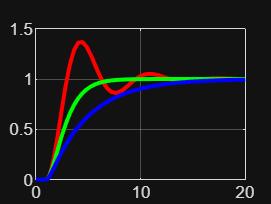

hold off;

Podemos ver que el sistema A (undamped) tiene:   

`SettlingTime: 12.2844`

`Overshoot: 37.0411`

`Para el sistema B (Critic damped):`

`RiseTime: 3.3652`

`Overshoot: 0`

`Para el sistema C (Overdamped):`

`RiseTime: 8.0174`

`Overshoot: 0`

`Como puede notar, para los dos últimos, el sistema no cuenta con la suficiente energía para sobrepasarse del valor de estado estacionario. También vemos como el sistema B (critic) es el perfecto equilibrio para alcanzar de forma  más rápida la meta sin vibraciones en la salida. El sistema C (overdamped) cumple con lo mismo, pero es mucho más lento.`

`Actividad 3`

Modelo de suspensión activa de vehículo (F1 context)

Planta: masa-resorte-amortiguador con masa 1500kg, k=20000N/m, b=1000Ns/m. Simular respuesta a perturbación escalón (bache). Medir %OS y ts. Contexto: así se diseñan sistemas de suspensión activa en motorsport.

t_para_f1 = 0:0.1:15;
num_f1 = [1];
den_f1 = [1500 1000 20000];
sys_f1 = tf([num_f1],[den_f1]);
info_sys_f1 = stepinfo(sys_f1)

info_sys_f1 = struct with fields:
         RiseTime: 0.3065
    TransientTime: 11.3845
     SettlingTime: 11.3845
      SettlingMin: 2.1902e-05
      SettlingMax: 8.7485e-05
        Overshoot: 74.9704
       Undershoot: 0
             Peak: 8.7485e-05
         PeakTime: 0.8604


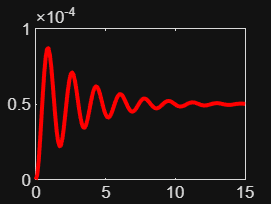

[y_f1,t_f1 ]= step(sys_f1, t_para_f1);
figure;
plot(t_f1, y_f1, "LineWidth",2, "Color" ,[1 0 0])

Obtenemos un overshoot de `74.9704% y un Sttilng time de 11.3845s.`

`Podemos notar que este sistema, primero tiene muy poco amortiguamiento, lo que hace que el overshoot sea tan alto, es decir, al pasar por un bache, el carro vibrará violentamente y tardará 11.38 segundos en volver a estar estable. Esto deja como resultado una suspensión incómoda, inestable y peligrosa. La respuesta se muestra en una escala de 10^-4 dado que la fuerza del escalón (1N) es muy poca para deformar un resorte con un k de 20000 N/m.`

`Actividad 4`

`Dado el ejercicio anterior, ahora se nos pide lo siguiente:`

Dado %OS=15% y ts=4s, encontrar ζ y ωn requeridos

Aplicar fórmulas inversas. Ubicar pólos deseados en plano-s. Construir G(s) del sistema deseado y verificar con stepinfo() en MATLAB que cumple las especificaciones 

%Calculo de parámetros
zeta = -(log(15/100))/sqrt(pi^2 + log(15/100)^2)

zeta = 0.5169

natural_frec = 1/zeta

natural_frec = 1.9345

%Construmios la G(s) del sistema
trans_function = tf(natural_frec^2, [1 2*natural_frec*zeta natural_frec^2])


trans_function =
 
        3.742
  -----------------
  s^2 + 2 s + 3.742
 
Continuous-time transfer function.


info_transf_function = stepinfo(trans_function)

info_transf_function = struct with fields:
         RiseTime: 0.8648
    TransientTime: 4.0622
     SettlingTime: 4.0622
      SettlingMin: 0.9239
      SettlingMax: 1.1500
        Overshoot: 14.9977
       Undershoot: 0
             Peak: 1.1500
         PeakTime: 1.8881


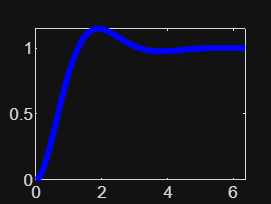

t_4_trans_function = 0:0.1:10;
[y_tf, t_tf] = step(trans_function);
figure;
plot(t_tf, y_tf, "LineWidth", 3, "Color",[0 0 1] )

%Para hallar los polos podemos usar el comando pole()

polos_tf = pole(trans_function)

polos_tf =   -1.0000 + 1.6560i
  -1.0000 - 1.6560i


`Obtuvimos entonces:`

`zeta = 0.5169`

`natural_frec = 1.9345`

`Con esto, se logra cumplir con el %OS solicitado, así como el settling time (4.06 s). Los polos encontrados para el sistema nos idican que este será estable (parte real es -1), mientras que la parte imaginaria nos dicta la frecuencia con la que oscila el sistema después de la entrada.`

**DIA 3**

Este día se repasaron los conceptos de Root Locus.

Se utiliza el ejercicio Skill Assessmente Exercie 8.5 del libro de Norman Nise.

$$G(s) = \frac{K(s - 2)(s - 4)}{s^2 + 6s + 25}$$

Vemos que los polos del sistema están en el semiplano derecho, por lo que al aumentar K, el sistema se hará inestable. Los polos son complejos, por lo que será oscilatorio para valores de K cercanos a cero.

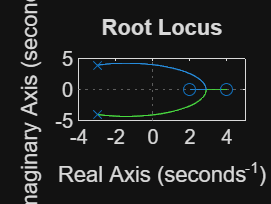

%close;
numerador = [1 -6 8];

denominador = [1 6 25];

sys = tf(numerador, denominador);

%Inciso a
rlocus(sys)


%Inciso b

%[K, polos] = rlocfind(sys)  % Si queremos hacerlo de forma gráfica e interactiva

margen = allmargin(sys) %allmargin() encuentra los criuces de forma analítica

margen = struct with fields:
     GainMargin: 1.0000
    GMFrequency: 4.0620
    PhaseMargin: [-1.1197e-04 180]
    PMFrequency: [4.0620 Inf]
    DelayMargin: [1.5468 0]
    DMFrequency: [4.0620 Inf]
         Stable: 1


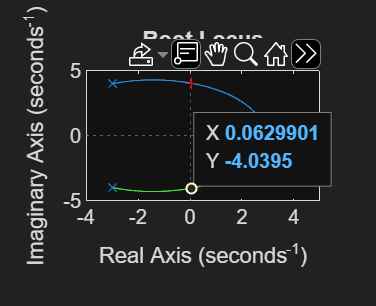

Punto Break-in

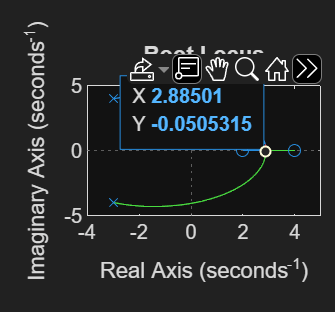

%Para hallar brake in de forma analítica:
syms s
numerador_sym = s^2 - 6*s + 8;

denominador_sym = s^2 + 6*s + 25;

k = (-denominador_sym / numerador_sym);

derivada_k = diff(k, s);
derivada_k_simplificada = simplify(derivada_k);
puntos_exactos = solve(derivada_k == 0, s);
double(puntos_exactos)

ans =    -5.7186
    2.8853


Como las raíces indican, solo el 2.88 se encuentra dentro del lugar de las raíces por lo que este es nuesgroo punto de ruptura. 

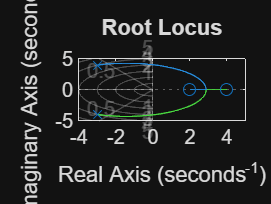

%Inciso e y f
%Dado un coefciente de amortiguamiento de 0.5 entonces:
angulo = acosd(0.5);
%Para facilitar saber donde cruza nuestro amortiguamiento:
numerador = [1 -6 8];

denominador = [1 6 25];

sys = tf(numerador, denominador);
figure;
rlocus(sys);

sgrid(0.5, []);

%rlocfind(sys);

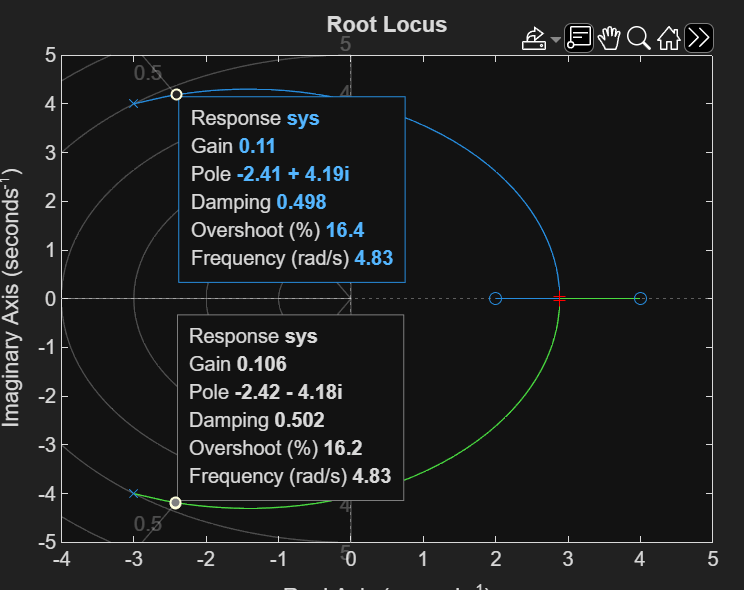

%Inciso g
figure;
rlocus(sys);

sgrid(0.5, []);

%rlocfind(sys);

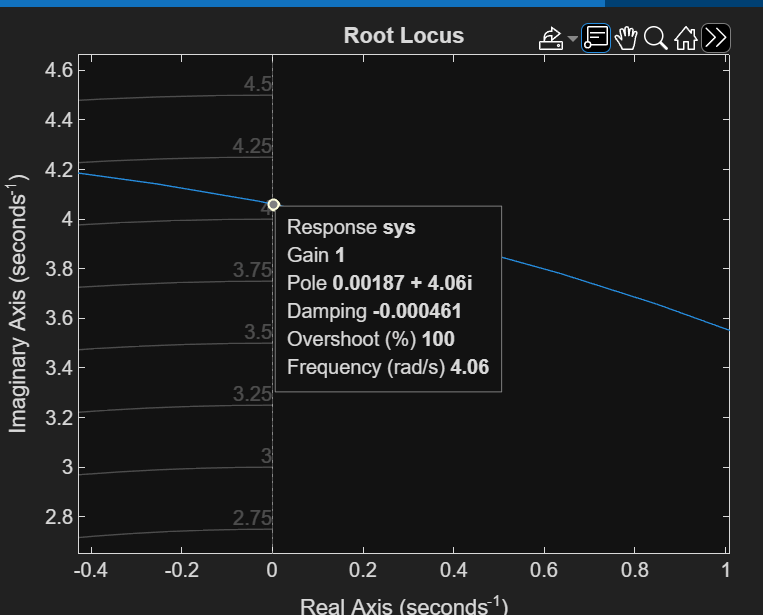

Se observa la ganacia antes de que las ramas se desplacen al lado derecho, lo cual se puede ver con la herramienta interactiva o usando la función "allmargin()" que ya habíamos usado, lo que nos indica que el margen de ganancia es de 1, es decir, ya está crítico y no le podemos mover más.

Actividad 2:

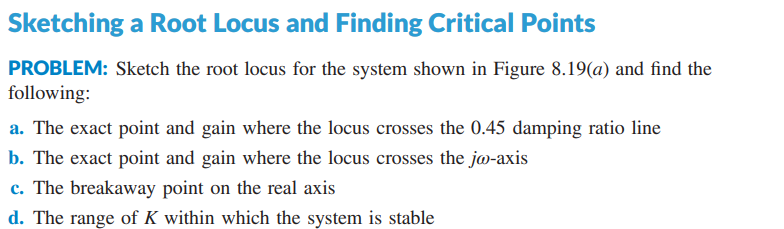

 Se incia con la gráfica solicitada para el lugar de las raíces:

%syms k; Esto no se usa dado que rlocus está diseñado para variar
%automáticamente la ganancia
%Analizamos el sistema en lazo abierto para el proceso de diseño
t_tf_act2_d2 = 0:0.1:10

t_tf_act2_d2 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


num_act2_dia2 = [1 -4 20];
den_act2_dia2 = conv(([1 2]),[1 4])

den_act2_dia2 =      1     6     8


tf_act2_dia2 = tf(num_act2_dia2, den_act2_dia2)


tf_act2_dia2 =
 
  s^2 - 4 s + 20
  --------------
  s^2 + 6 s + 8
 
Continuous-time transfer function.


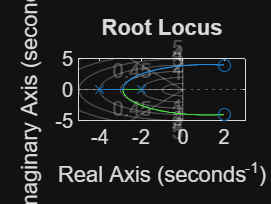

%info_tf_act2_d2 = stepinfo(tf_act2_dia2)
%[y_tf_act2_d2, t_tf_act_d2] = step(tf_act2_dia2, t_tf_act2_d2)
%figure;
%plot(t_tf_act2_d2 ,y_tf_act2_d2, "LineWidth", 3, "Color", [0 1 0])

%Inciso A. The exact point and gain where locus crosses the 0.45 damping
%ratio line
%Usamos el comando sgrid(), para graficar la recta dentro de la gráfica del
%locus, usamos rlocus(), para graficar el lugar de las raíces

figure;
rlocus(tf_act2_dia2)
sgrid(0.45, [])

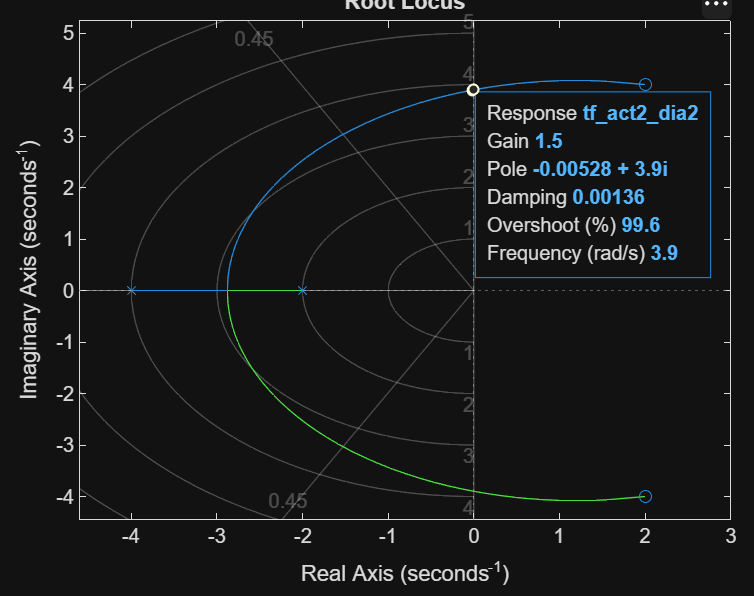

Observamos que el sistema tiene sus ceros en el semiplano derecho, lo que quiere decir que contamos con una ganacia cr´tica para la que el sistema se volverá inestable. En este caso, sería una ganacia menor a 1.5. Ahora, la ganacia y el sitio exacto donde el sistema atraviesa el damping ratio de 0.45:

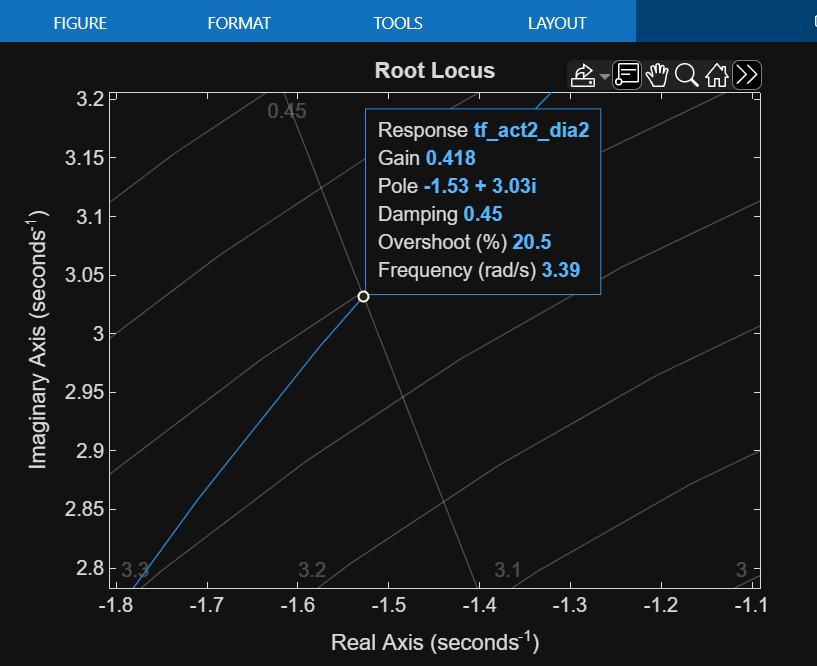

Se registra una ganancia de 0.418, y polos conjugados para


$$S_{1,2} =-1\ldotp 55\pm 3\ldotp 03i$$


%Inciso B


Como se mencionó en el inciso anterior, ese valor corresponde a una ganacia de 1.5 y aproximadamente se ubica en los conjugados:


$$S_{1,2} =0\pm 3\ldotp 9\;i$$


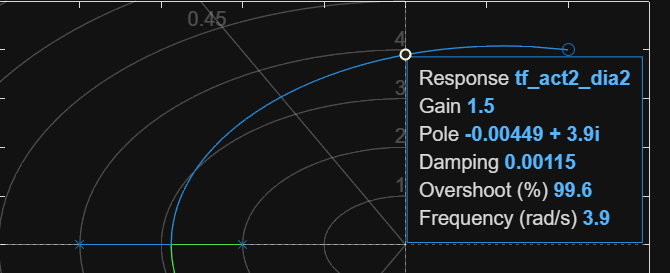

La ganacia crítica de 1.5 para que el sistema se vuelva inestable se puede validar ráidamente utilizando el criterio de Routh-Hurtwiz:


$$

$$G(s) = \frac{s^2 - 4s + 20}{(s+2)(s+4)} = \frac{s^2 - 4s + 20}{s^2 + 6s + 8}$$


$$1 + K \cdot G(s) = 0$$


$$(s^2 + 6s + 8) + K(s^2 - 4s + 20) = 0$$

$$s^2(1+K) + s(6-4K) + (20K + 8) = 0$$


$$6 - 4K > 0 ; 6 > 4K ; K < 1.5$$


$$K_{\text{crítica}} = 1.5$$$$


%Inciso C


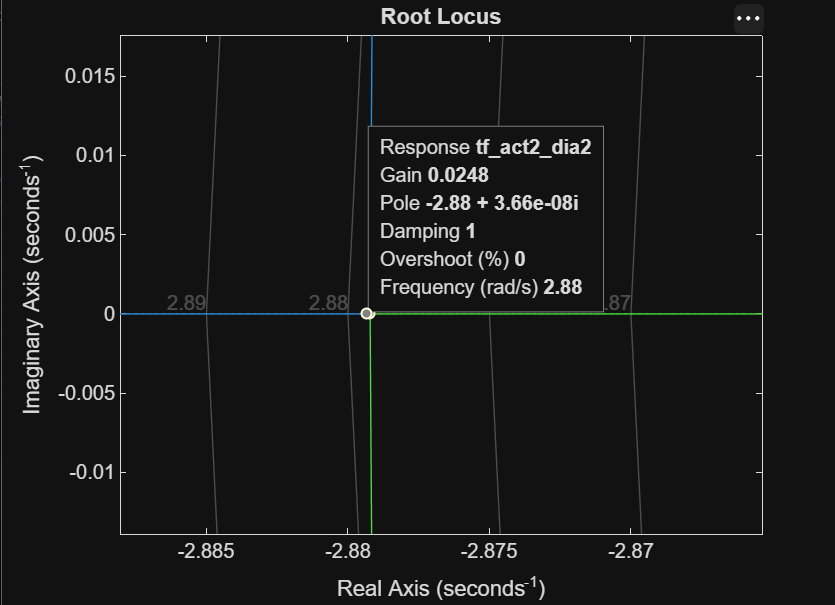

Obtenemos que el breakway point se encuentra aproximadamente en -2.88 en el eje real.

%Inciso D

Como se aclaró en el inciso a, la ganacia adquiere un valor de 0.418 al tener un damping ratio de 0.45.  Si usamos este damping ratio como un criterio de diseño, podríamos  establecer que K no debe ser mayor a 0.418. Si tuviéramos un criterio, como un settling time máximo, podríamos definir un K mínmo.

%Inciso Experimental


En este punto vamos a ver la respuesta al escalón del sistema en lazo cerrado del sistema original, y luego la respuesta del mismo sistema pero con la ganacia que acabamos de encontrar, usando un damping ratio de 0.45 como criterio de diseño.

sys_lazo_cerrado_tf_act2_d2 = feedback(tf_act2_dia2,1);
info_tf_act2_d2 = stepinfo(sys_lazo_cerrado_tf_act2_d2)

info_tf_act2_d2 = struct with fields:
         RiseTime: 0.7298
    TransientTime: 8.0535
     SettlingTime: 7.3143
      SettlingMin: 0.4469
      SettlingMax: 1.1220
        Overshoot: 57.0759
       Undershoot: 0
             Peak: 1.1220
         PeakTime: 1.1755


[y_tf_act2_d2, t_tf_act_d2] = step(sys_lazo_cerrado_tf_act2_d2, t_tf_act2_d2);
%Ahora miramos la respuesta con la ganacia encontrada
k_find = 0.418

k_find = 0.4180

sys_lazo_cerrado_tf_act2_d2_k = feedback(k_find*tf_act2_dia2,1);
info_tf_act2_d2_k = stepinfo(sys_lazo_cerrado_tf_act2_d2_k)

info_tf_act2_d2_k = struct with fields:
         RiseTime: 0.8699
    TransientTime: 2.7338
     SettlingTime: 2.7192
      SettlingMin: 0.4638
      SettlingMax: 0.6102
        Overshoot: 19.4081
       Undershoot: 0
             Peak: 0.6102
         PeakTime: 1.2976


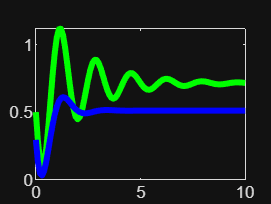

[y_tf_act2_d2_k, t_tf_act_d2_k] = step(sys_lazo_cerrado_tf_act2_d2_k, t_tf_act2_d2);


figure;
plot(t_tf_act2_d2 ,y_tf_act2_d2, "LineWidth", 3, "Color", [0 1 0])
hold on;
plot(t_tf_act2_d2 ,y_tf_act2_d2_k, "LineWidth", 3, "Color", [0 0 1])
hold off;

Se nota a primera vista que el sistema original (curva verde), oscilaba con mayor amplitud. Al introducir al sistema una ganacia de 0.418, se logran frenar estas socilaciones y se baja el Overshoot de 57.07% a 19.40%, lo que valida que un damping ratio ayuda a estabilizar dinámicamente la planta.

Al ubicar los polos con la variación del k seleccionado, se logra disminuir el ts, de 7.31 s a 2.7 s. esto muestra que un simple ajuste de ganacia permite que el sistema responda y se estabilice más de dos veces más rápido.

No obstante, como puede ver, al bajar la ganaica para mejorar la estabilidad del sistema, ya que no se alcanza el mismo valor en estado estacionario, lo que hace necesario un controlador más completo (PID) para alcanzar todas las métricas de diseño que se soliciten. 

ACTIVIDAD 3

Diseño de un Controlador Proporcional para un Robot Pick-and-Place

**Contexto Industrial**

En líneas de manufactura automatizada, los brazos robóticos (como el **ABB IRB 1200**) requieren un control de posición extremadamente preciso en sus ejes rotacionales para realizar tareas de *Pick-and-Place* (tomar y colocar piezas). Si el movimiento del eje es muy brusco o tiene demasiado sobreimpulso, el robot podría golpear la estación de trabajo, dañar los componentes electrónicos que transporta o perder precisión debido a vibraciones estructurales.

**Definición de la Planta**

El comportamiento dinámico del motor y los engranajes de uno de los ejes principales del robot se modela mediante la siguiente función de transferencia en lazo abierto $G(s)$, la cual presenta un comportamiento de tercer orden con un integrador puro (sistema tipo 1):


$$G\left(s\right)=\frac{1}{s\left(s+2\right)\left(s+8\right)}=\frac{1}{s^3 +10s^2 +16s}$$


**Enunciado del Problema**

Se solicita diseñar e implementar un **Controlador Proporcional K** en lazo cerrado para regular la posición del eje del robot ABB, garantizando que al realizar un movimiento rápido (entrada escalón) el sistema cumpla estrictamente con los siguientes criterios de rendimiento:

- **Sobreimpulso máximo (%OS):** Exactamente del 5%.

- **Estabilidad:** El sistema debe mantenerse dentro del margen de operación estable en todo momento.

Desarrollo:

%Inciso A
num_act3_d2 = 1;
den_act3_d2 = [1 10 16 0];
tf_act3_d2 = tf(num_act3_d2, den_act3_d2); %El eneunciado dice que esta es toda la planta
sys_act3_d2 = feedback(tf_act3_d2,1)


sys_act3_d2 =
 
             1
  -----------------------
  s^3 + 10 s^2 + 16 s + 1
 
Continuous-time transfer function.


%Con un %OS de 5% se debe encontrar el damping ratio correspondiente
%Con eso se encuentra la ganacia que requiere el sistema
OS_act3_d2 = 5/100;
zeta_act3_d2 = -log(OS_act3_d2)/(sqrt(pi^2 + log(OS_act3_d2)^2))

zeta_act3_d2 = 0.6901


%


Con un damping ratio de 0.69, ubicamos la ganacia en lugar de las raíces:

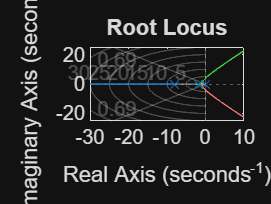

rlocus(sys_act3_d2)
sgrid(0.6901,[])

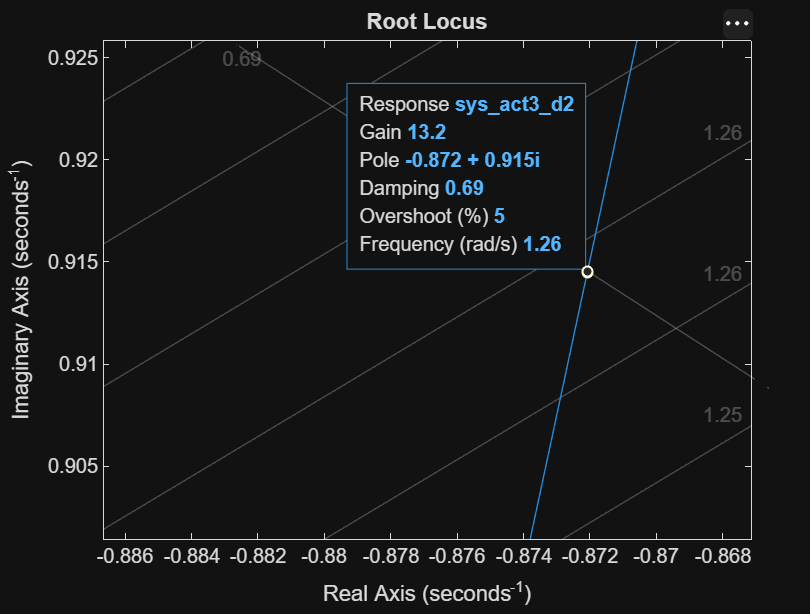

Obtenemos una ganacia de 13.2.  Usaremos este K como límite máximo debido a el %OS solicitado.

Comparamos ambos sistemas, el original, y al que se le implementó K.

t_act3_d3_abb = 0:0.1:10 

t_act3_d3_abb =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


info_sys_act3_d2 = stepinfo(sys_act3_d2)

info_sys_act3_d2 = struct with fields:
         RiseTime: 33.7438
    TransientTime: 60.7193
     SettlingTime: 60.7193
      SettlingMin: 0.9003
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 112.4173


[y_act3_d2, t_act3_d2] = step(sys_act3_d2); 

k_act3_d2 = 13.2

k_act3_d2 = 13.2000

sys_act3_d2_k = feedback(k_act3_d2*sys_act3_d2,1);
info_sys_act3_d2_k = stepinfo(sys_act3_d2)

info_sys_act3_d2_k = struct with fields:
         RiseTime: 33.7438
    TransientTime: 60.7193
     SettlingTime: 60.7193
      SettlingMin: 0.9003
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 112.4173


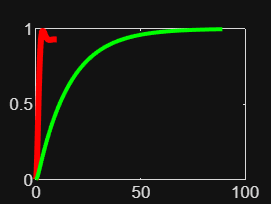

[y_act3_d2_k, t_act3_d2_k] = step(sys_act3_d2_k,t_act3_d3_abb ); 
figure;
plot(t_act3_d3_abb, y_act3_d2_k,"LineWidth", 3, "Color", [1 0 0])
hold on;
plot(t_act3_d2, y_act3_d2, "LineWidth", 2, "Color", [0 1 0])
hold off;

**DIA 4**

Este día nos centramos en  en el diseño de controladores PID. Iniciamos el día de hoy, resolviendo el ejejmplo 9.5 propuesto en el libro de Norman Nise.

Actividad 1

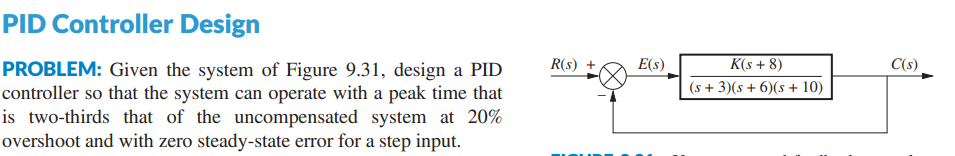

Entonces:

Especificaciones de diseño:

- Overshoot de 20%

- $T_p$ dos tercios del sistema original

Primero graficamos el lugar de las raíces del sistema:

num_act_d4 = [1 8];
den_act_d4 = poly([-3 -6 -10]); %Usamos poly() para evitar equivocaciones
tf_act1_d4 = tf(num_act_d4, den_act_d4)


tf_act1_d4 =
 
            s + 8
  --------------------------
  s^3 + 19 s^2 + 108 s + 180
 
Continuous-time transfer function.


os_act1_d4 = 20/100

os_act1_d4 = 0.2000

zeta_act1_d4 = -log(os_act1_d4)/sqrt(pi^2 + (log(os_act1_d4))^2)

zeta_act1_d4 = 0.4559

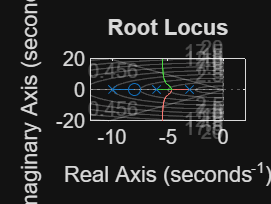

rlocus(tf_act1_d4)
sgrid(zeta_act1_d4, [])

De lo cual obtenemos un damping ratio de 0.4559, ganancia de k=122 y una frecuencia natural de 11.9.

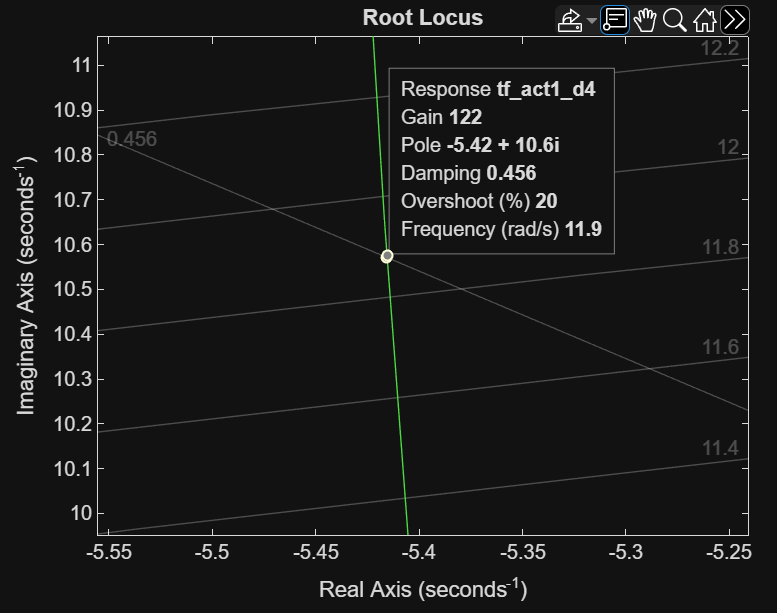

%ahora solo queda saber cuál es el tiempo pico actual
tp_act1_d4 = pi/(11.9 * sqrt(1 - (zeta_act1_d4)^2))

tp_act1_d4 = 0.2966

tp_act1_d4_target = tp_act1_d4 * (2/3)

tp_act1_d4_target = 0.1978

Tenemos un tiempo pico de 0.2966 s para el sistema actual y de 0.1978 para el sistema deseado. Con estos datos ya podemos ubicar los polos que queremos en nuestro sistema

damped_natural_frec_act1_d4 = pi/tp_act1_d4_target

damped_natural_frec_act1_d4 = 15.8866

real_part_act1_d4 = (damped_natural_frec_act1_d4 * zeta_act1_d4)/(sqrt(1-(zeta_act1_d4)^2))

real_part_act1_d4 = 8.1387

Tenemos polos conjugados con una parte real de -8.1387 y una imaginaria de 15.8866. Recordemos que la atenuación (parte real) se calcula como la distancia absoluta al eje imaginario, por lo que le asignamos el signo "-" de forma manual.

Ahora aplicamos la condición del ángulo y tenemos que:

- Ceros: -8

- Polos: -3, -6, y -10.

%Teniendo como polo deseado s_d = -8.1387 + j15.8866 
angulo_c1_act1_d4 = rad2deg(atan2(15.8866, -8.1387 - (-8)))

angulo_c1_act1_d4 = 90.5002

angulo_p1_act1_d4 = rad2deg(atan2(15.8866, -8.1387 - (-3)))

angulo_p1_act1_d4 = 107.9244

angulo_p2_act1_d4 = rad2deg(atan2(15.8866, -8.1387 - (-6) ))

angulo_p2_act1_d4 = 97.6672

angulo_p3_act1_d4 = rad2deg(atan2(15.8866, -8.1387 - (-10) ))

angulo_p3_act1_d4 = 83.3176

Obtenemos entonces:

Angulo C1 = 90.5002

Angulo P1 = 107.9244

Angulo P2 =  97.6672

Angulo P3 =  83.3176

%Recordemos que la condición del Ángulo
%Suma de ceros - suma de polos = -180°
ang_aportado_act1_d4 = -180 - angulo_c1_act1_d4 + angulo_p1_act1_d4 + angulo_p2_act1_d4 + angulo_p3_act1_d4

ang_aportado_act1_d4 = 18.4090

Obtenemos un valor 18.4090°. Este es el angulo que el nuevo cero del controlador PD debe aportar para que los polos pasen por nuestro punto de diseño.

Ahora sabemos que el ángulo aportado desde el cero hacia el nuevo polo es 18.4, podemos saber donde ubicarlo.

d_act_d4 = damped_natural_frec_act1_d4 / tand(ang_aportado_act1_d4)

d_act_d4 = 47.7319

Donde el "d" calculado corrresponde a la distancia desde la parte real del polo deseado, hasta el cero que vamos a ubicar con el controlador.

De esta forma, el cero del controlador diseñado va en: 

ubi_cero_act1_d4 = -real_part_act1_d4 - d_act_d4

ubi_cero_act1_d4 = -55.8706

Ahora si se aplica la condición de magnitud.

Reemplazamos el cero deseado para averiguar la ganacia necesaria para atravesar por ese punto.

num_polo_d_act1_d4 = poly([-8 ubi_cero_act1_d4]);
den_polo_d_act1_d4 = poly([-3 -6 -10])

den_polo_d_act1_d4 =      1    19   108   180


s_d_act1_d4 = -8.1387 + 15.8866i;
%Podemos evaluar el valor de un polinomio en un sitio
%especificado usando polyvals()
mag_num_act1_d4 = abs(polyval(num_polo_d_act1_d4, s_d_act1_d4))

mag_num_act1_d4 = 799.2250

mag_den_act1_d4 = abs(polyval(den_polo_d_act1_d4, s_d_act1_d4))

mag_den_act1_d4 = 4.2812e+03


%Ahora invertimos la fracción para ahallar K
K_design_act1_d4 = mag_den_act1_d4 / mag_num_act1_d4 

K_design_act1_d4 = 5.3566

Con esto acabamos la parte transitoria. Para cumplir ocn la especificación de un error de cero ante una entrada de escalón, es necesario añadir un integrador puro en el origen y un cero muy cerca del origen. Usaremos un cero ubicado en -0.1.

%Definimos el controlador PID
Kp_act1_d4 = 299.81211;
Kd_act1_d4 = 5.3566;
Ki_act1_d4 = 29.927;

%Para crear el PID usamos el comando pid()
Controlador_PID_act1_d4 = pid(Kp_act1_d4, Ki_act1_d4, Kd_act1_d4)


Controlador_PID_act1_d4 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 300, Ki = 29.9, Kd = 5.36
 
Continuous-time PID controller in parallel form.



%Ahora cerramos el sistema

sys_act1_d4 = feedback(Controlador_PID_act1_d4 * tf_act1_d4, 1);
sys_act1_d4_sin_control = feedback(tf_act1_d4, 1);
info_sys_act1_d4 = stepinfo(sys_act1_d4)

info_sys_act1_d4 = struct with fields:
         RiseTime: 0.0876
    TransientTime: 13.0183
     SettlingTime: 13.0183
      SettlingMin: 0.8947
      SettlingMax: 1.1383
        Overshoot: 13.8298
       Undershoot: 0
             Peak: 1.1383
         PeakTime: 0.1764


info_sys_act1_d4_sc = stepinfo(sys_act1_d4_sin_control)

info_sys_act1_d4_sc = struct with fields:
         RiseTime: 0.7957
    TransientTime: 1.4116
     SettlingTime: 1.4116
      SettlingMin: 0.0384
      SettlingMax: 0.0425
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0425
         PeakTime: 2.3900


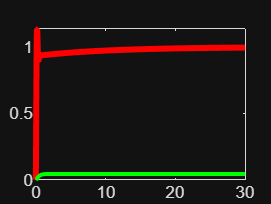


t_simu_act1_d4 = 0:0.005:30;

[y_act1_d4, t_simu_act1_d4_graph] = step(sys_act1_d4, t_simu_act1_d4);
[y_act1_d4_sc, t_simu_act1_d4_graph_sc] = step(sys_act1_d4_sin_control, t_simu_act1_d4);

figure;
plot(t_simu_act1_d4_graph, y_act1_d4, "LineWidth", 3, "Color", [1 0 0])
hold on;
plot(t_simu_act1_d4_graph_sc, y_act1_d4_sc, "LineWidth", 2, "Color", [0 1 0])
hold off;

Puede observar que la respuesta en los 30 segundos de simulación, la rspuesta del sistema con PID se establece en 0.99. No obstante, con más tiempo de simulación, este valor llegaría a 1, solo que la componente integral se demora su tiempo en hacer efecto.

El sistema llega a su pico rápidamente gracias a la componente del PD, alcanza su pico a los 0.17 segundos. Esto es una mejora incomparable frente al sistema sin PID, ya que nisiquiera llega al valor solicitado. Esta disparidad en las gráficas es debido a la disparidad en cuando a ganacias en DC.

Nótese que aunque el sistema sea de tercer orden, nótese que la introducción de la componente derivativa añade un cero a -55.87, lo que hace que esté a una distancia mayor a 5 sobre los polos dominantes del sistema y hace que la aproximación de segundo orden sea válida. 

ACTIVIDAD 2

Control de Posición de un Sistema Mecánico Translacional

En el laboratorio de automatización y robótica, se requiere controlar la posición de una etapa de traslación lineal modelada como un sistema mecánico masa-resorte-amortiguador. El comportamiento dinámico de la planta en lazo abierto responde a los parámetros físicos nominales: masa $m=1\;\textrm{kg}$, constante elástica del resorte $k=5\;\frac{N}{m}$, y coeficiente de amortiguamiento viscoso $b=0\ldotp 5\;\frac{\mathrm{Ns}}{m}$.

La función de transferencia del sistema que relaciona la fuerza de entrada  U(s) con la posición de salida Y(s) está dada por:


$$G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{1}{s^2 +0\ldotp 5s+5}$$


Objetivo General**:**Diseñar e implementar de manera secuencial un controlador PID analógico continuo empleando la técnica del Lugar Geométrico de las Raíces (LGR) para garantizar que el sistema cumpla con exigencias estrictas de desempeño transitorio y estacionario ante una entrada tipo escalón unitario.

Especificaciones técnicas de diseño:

- Sobreimpulso Máximo de (%OS) $\le 8%$

- Tiempo de Asentamiento $t_s \le 2s$

- Error en estado estacionacionario $e_{\mathrm{ss}} =0$ para entradas de escalón 

Desarrollo:

%Inciamos por definir nuestro sistema:
num_act2_d4 = 1;
den_act2_d4 = [1 0.5 5];
tf_act2_d4 = tf(num_act2_d4, den_act2_d4)


tf_act2_d4 =
 
         1
  ---------------
  s^2 + 0.5 s + 5
 
Continuous-time transfer function.


OS_act2_d4 = 8/100

OS_act2_d4 = 0.0800

zeta_act2_d4 = -log(OS_act2_d4)/sqrt(pi^2 + (log(OS_act2_d4))^2)

zeta_act2_d4 = 0.6266

%Graficamos el lugar de las raíces
rlocus(tf_act2_d4)
sgrid(zeta_act2_d4, []);


Esto nos permite observar que el sistema original no atraviesa el damping deseado, por lo que acabaremos la locación del polo deseado.

ts_act2_d4 = 2;
natural_freq_act2_d4 = 4/(zeta_act2_d4 * ts_act2_d4)

natural_freq_act2_d4 = 3.1919

damped_nat_freq_act2_d4 = natural_freq_act2_d4 * sqrt(1 - (zeta_act2_d4)^2)

damped_nat_freq_act2_d4 = 2.4877

real_part_act2_d4 = -zeta_act2_d4 * natural_freq_act2_d4

real_part_act2_d4 = -2

imaginary_part_act2_d4 = damped_nat_freq_act2_d4

imaginary_part_act2_d4 = 2.4877

Ese es nuestro polo deseado, ahora tenemos que verificar la condición de ángulo para saber donde ubicar el cero de nuestra componente derivativa.

Para ello, factorizamos el denominador de la fracción para ver donde está cada polo. No tenemos ceros debido a que en el numerador solo hay un uno (1).

%Usamos la función roots() para obtener las raíces del denominador.
roots(den_act2_d4)

ans =   -0.2500 + 2.2220i
  -0.2500 - 2.2220i


Obtenemos como resultado:

$S_1 =$-0.250000000000000 + 2.222048604328898i

$S_2 =$-0.250000000000000 - 2.222048604328898i

%Ahora podemos calcular los ángulos desde los polos hasta nuestro polo
%deseado
%ang_p3_act2_d4 = (atan2d(imaginary_part_act2_d4,real_part_act2_d4))
ang_p1_act2_d4 = (atan2d(imaginary_part_act2_d4 - 2.2220,real_part_act2_d4 + 0.25))

ang_p1_act2_d4 = 171.3677

ang_p2_act2_d4 = (atan2d(imaginary_part_act2_d4 + 2.2220,real_part_act2_d4 + 0.25))

ang_p2_act2_d4 = 110.3838

ang_p3_act2_d4 = (atan2d(imaginary_part_act2_d4,real_part_act2_d4))

ang_p3_act2_d4 = 128.7980


%Para saber qué angulo aporta el nuevo cero:
ang_aportado_act2_d4 = -180 + ang_p1_act2_d4 + ang_p2_act2_d4

ang_aportado_act2_d4 = 101.7515

%Para saber a que distancia se encuentra de la parte real de los los polos
%deseados

d_act2_d4 = abs(imaginary_part_act2_d4/tand(ang_aportado_act2_d4))

d_act2_d4 = 0.5175


%Para saber si va a laizquierda o la derecha de la parte real del cero
%deseado

if (0 < ang_aportado_act2_d4) &&  (ang_aportado_act2_d4 < 90)
    cero_position_act2_d4 = real_part_act2_d4 - d_act2_d4
else
    cero_position_act2_d4 = real_part_act2_d4 + d_act2_d4
end

cero_position_act2_d4 = -1.4825


%Ahora empezamos a aplicar la magnitud condition
desired_pole = real_part_act2_d4 + imaginary_part_act2_d4*1i 

desired_pole = -2.0000 + 2.4877i


% Usarmos un polo en el origen con su respecitvo cero ubicado en S = -0.1 según el estándar
%new_num_act2_d4 = poly(cero_position_act2_d4)
%mag_num_act2_d4 = abs(polyval(new_num_act2_d4, desired_pole))
%mag_den_act2_d4 = abs(polyval(den_act2_d4, desired_pole))
%K_design_act2_d4 = mag_den_act2_d4/mag_num_act2_d4
num_ctrl = conv([1 -cero_position_act2_d4], [1 -0.25]);  % ceros del controlador
den_ctrl = [1 0];                                        % polo en origen

% Condición de magnitud evaluada en polo deseado
mag_planta_num   = abs(polyval(num_act2_d4, desired_pole));
mag_planta_den   = abs(polyval(den_act2_d4, desired_pole));
mag_ctrl_num     = abs(polyval(num_ctrl, desired_pole));
mag_ctrl_den     = abs(polyval(den_ctrl, desired_pole));

K_design_act2_d4 = (mag_planta_den * mag_ctrl_den) / (mag_planta_num * mag_ctrl_num)

K_design_act2_d4 = 3.3307

%K_design_act2_d4 = 10;
%z_pd_act2_d4 = abs(cero_position_act2_d4); 
z_pd_act2_d4 = natural_freq_act2_d4; 
% Pasamos el cero a valor positivo para las fórmulas
kd_act2_d4 = K_design_act2_d4;
kp_act2_d4 = K_design_act2_d4 * (z_pd_act2_d4 + 0.25);
ki_act2_d4 = K_design_act2_d4 * 0.25 * z_pd_act2_d4;
designed_control_act2_d4 = pid(kp_act2_d4, ki_act2_d4, kd_act2_d4)


designed_control_act2_d4 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 11.5, Ki = 2.66, Kd = 3.33
 
Continuous-time PID controller in parallel form.


sys_controlled_act2_d4 = feedback(designed_control_act2_d4 * tf_act2_d4, 1)


sys_controlled_act2_d4 =
 
     3.331 s^2 + 11.46 s + 2.658
  ---------------------------------
  s^3 + 3.831 s^2 + 16.46 s + 2.658
 
Continuous-time transfer function.


sys_act2_d4 = feedback(tf_act2_d4,1)


sys_act2_d4 =
 
         1
  ---------------
  s^2 + 0.5 s + 6
 
Continuous-time transfer function.


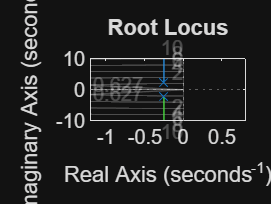

rlocus(sys_controlled_act2_d4)

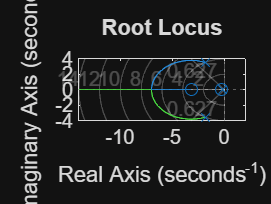

sgrid(zeta_act2_d4, [])

t_act2_d4 = 0:0.005:6;
info_control_sys_act2_d4 = stepinfo(sys_controlled_act2_d4)

info_control_sys_act2_d4 = struct with fields:
         RiseTime: 0.3514
    TransientTime: 16.6069
     SettlingTime: 16.6069
      SettlingMin: 0.6886
      SettlingMax: 0.9989
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9989
         PeakTime: 33.6433


info_sys_act2_d4 = stepinfo(sys_act2_d4)

info_sys_act2_d4 = struct with fields:
         RiseTime: 0.4609
    TransientTime: 15.5760
     SettlingTime: 15.5760
      SettlingMin: 0.0792
      SettlingMax: 0.2874
        Overshoot: 72.4367
       Undershoot: 0
             Peak: 0.2874
         PeakTime: 1.2825


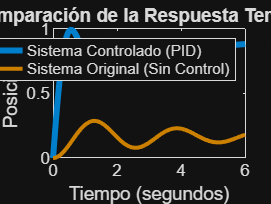

% Simulación 1: Sistema Controlado
[y_act2_d4, t_y_act2_d4] = step(sys_controlled_act2_d4, t_act2_d4);

% Simulación 2: Sistema Sin Control
[y_act2_d4_wc, t_y_act2_d4_wc] = step(sys_act2_d4, t_act2_d4);
figure;
plot(t_y_act2_d4, y_act2_d4, "LineWidth",3, "Color", [0 0.5 0.8] )
hold on;
plot(t_y_act2_d4_wc, y_act2_d4_wc, "LineWidth",2, "Color", [0.8 0.5 0] )
legend('Sistema Controlado (PID)', 'Sistema Original (Sin Control)');
xlabel('Tiempo (segundos)');
ylabel('Posición');
title('Comparación de la Respuesta Temporal');
hold off;

Actividad 3: 

Control de Flujo de Lodo de Perforación con Tiempo Muerto (Oil & Gas)

En las operaciones de perforación de pozos petroleros, el control preciso del flujo del lodo de perforación es crítico para mantener la presión hidrostática y garantizar la estabilidad del pozo. Debido a la longitud de las líneas de tubería y a la dinámica de la válvula de control del bloque de bombeo, el sistema presenta un retraso físico significativo (tiempo muerto) entre la señal enviada a la válvula y el cambio real en el caudal medido por el flujómetro.

La dinámica del proceso en lazo abierto se modela mediante una función de transferencia de primer orden con tiempo muerto (FOPDT):


$$G\left(s\right)=\frac{2e^{-0\ldotp 5s} }{3s+1}$$


Diseñar, simular y comparar el desempeño de un controlador PID continuo para el sistema de control de flujo, evaluando la efectividad de una sintonización empírica clásica frente a una sintonización basada en la geometría de raíces.

**Especificaciones y Requerimientos Técnicos**

- **Aproximación del Tiempo Muerto:** Utilizar una aproximación de **Padé de primer orden** para representar el retraso de $0\ldotp 5\;s$ en forma de función de transferencia racional en MATLAB.

- **Estrategia A (Ziegler-Nichols por Margen de Estabilidad):** Encontrar la ganancia crítica $K_{\mathrm{cr}}$ y el período crítico $P_{\mathrm{cr}\;}$del sistema aproximado mediante el Lugar Geométrico de las Raíces para calcular los parámetros PID según la tabla clásica de Z-N.

- **Estrategia B (Lugar Geométrico de las Raíces - LGR):** Diseñar un controlador PID por asignación de polos que busque compensar el efecto del retraso, apuntando a un factor de amortiguamiento $\zeta =0\ldotp 707$ y un tiempo de asentamiento menor a $3\;s$.

- **Análisis Comparativo:** Graficar en una misma figura la respuesta al escalón unitario de ambos sistemas controlados, evaluando el sobreimpulso (%OS), el tiempo de asentamiento ($t_s$) y la estabilidad robusta.

Desarrollo:

%Inciso 1
%Aplicamos la aproximación de Padé de primer orden:
num_retraso_act3_d4 = [-0.5/2 1];
den_retraso_act3_d4 = [0.5/2 1];
retraso_act3_d4 = tf(num_retraso_act3_d4, den_retraso_act3_d4)


retraso_act3_d4 =
 
  -0.25 s + 1
  -----------
  0.25 s + 1
 
Continuous-time transfer function.


%Definimos la planta original
num_act3_d4 = 2;
den_act3_d4 = [3 1];
tf_partial_act3_d4 = tf(num_act3_d4, den_act3_d4)


tf_partial_act3_d4 =
 
     2
  -------
  3 s + 1
 
Continuous-time transfer function.


tf_act3_d4 = retraso_act3_d4 * tf_partial_act3_d4


tf_act3_d4 =
 
       -0.5 s + 2
  ---------------------
  0.75 s^2 + 3.25 s + 1
 
Continuous-time transfer function.


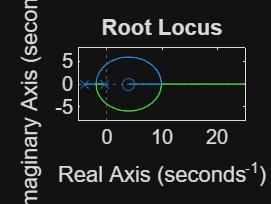

%Inciso 2. Estrategia A. Con el sistema definido graficamos root locus para concer la
%frecuecia crítica y la ganacia crítica
figure;
rlocus(tf_act3_d4)

Obtenemos una $K_{\mathrm{cr}} =$6.54 y $\omega_{\mathrm{cr}} =4\ldotp 33$

Para el PID entonces:

kcr_act3_d4 = 6.54;
pcr_act3_d4 = 2*pi/4.33;
kp_act3_d4 = 0.6 * kcr_act3_d4

kp_act3_d4 = 3.9240

ki_act3_d4 = kp_act3_d4/(0.5 * pcr_act3_d4)

ki_act3_d4 = 5.4084

kd_act3_d4 = (0.125 * pcr_act3_d4)*kp_act3_d4   

kd_act3_d4 = 0.7118

controller_designed_act3_d4_zn = pid(kp_act3_d4, ki_act3_d4, kd_act3_d4)


controller_designed_act3_d4_zn =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 3.92, Ki = 5.41, Kd = 0.712
 
Continuous-time PID controller in parallel form.


sys_controlled_act3_d4_zn = feedback(controller_designed_act3_d4_zn * tf_act3_d4,1)


sys_controlled_act3_d4_zn =
 
  -0.3559 s^3 - 0.5385 s^2 + 5.144 s + 10.82
  ------------------------------------------
   0.3941 s^3 + 2.712 s^2 + 6.144 s + 10.82
 
Continuous-time transfer function.


t_c_sys_zn = 0:0.01:30;
info_sys_zn_act3_d4 = stepinfo(sys_controlled_act3_d4_zn)

info_sys_zn_act3_d4 = struct with fields:
         RiseTime: 0.2646
    TransientTime: 3.1644
     SettlingTime: 4.2924
      SettlingMin: 0.8852
      SettlingMax: 1.5106
        Overshoot: 51.0595
       Undershoot: 90.2963
             Peak: 1.5106
         PeakTime: 1.0682


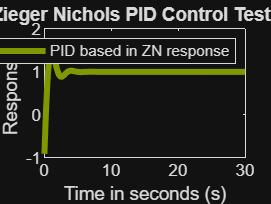

[y_zn_act3_d4, t_zn_act3_d4] = step(sys_controlled_act3_d4_zn, t_c_sys_zn);
figure;
plot(t_c_sys_zn,y_zn_act3_d4, "LineWidth", 3, "Color", [0.5 0.6 0])
title("Zieger Nichols PID Control Testing")
legend("PID based in ZN response");
xlabel("Time in seconds (s)");
ylabel("Response")

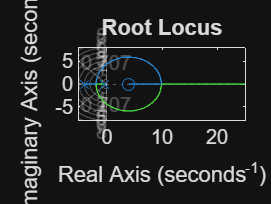


%Inciso 3. Root Locus
%Se debe cumplir con un zeta de 0.707 y un tiempo de asentamiento menor a 3s.
figure;
rlocus(tf_act3_d4)
sgrid(0.707, []);

Revisamos el punto en el que el Root Locus atraviesa la línea del damping ratio establecido

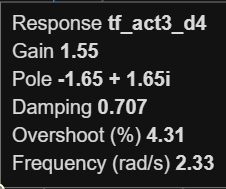

Como puede notar, el lugar de las raíces del sistema, si pasa por el punto deseado. Por eso, no es necesario que calculemos el punto por el que deseemos que pase el sistema . Esto muestra que el sistema por si solo, si es capaz de alcanzar las condiciones que requerimos, no obstante, para asegurarnos de que no exista error en estado estacionario, se diseñará un controlador basado en PID, tanto para corregir ese error en esato estacionario, como para agregar un seguro en caso de

%desired pole
desired_pole_act3_d4 = -1.65 + 1.65*1i;
real_part_act3_d4 = -1.65;
imaginary_part_act3_d4 = 1.65; %No ponemos la i porque atan2d solo recibe reales
%Ahora verificamos la condición de ángulo para los polos y ceros del
%sistema para saber donde ubicar el cero de la componente derivativa
%Sacamos las ráices de la función de transferencia
[num_complete_act3_d4, den_complete_act3_d4] = tfdata(tf_act3_d4,"v");
ceros_act3_d4 = roots(num_complete_act3_d4)

ceros_act3_d4 = 4

poles_act3_d4 = roots(den_complete_act3_d4)

poles_act3_d4 =    -4.0000
   -0.3333


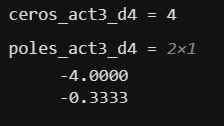

Con las raíces determinamos los ángulos:

ang_c1_act3_d4 = atan2d(imaginary_part_act3_d4, real_part_act3_d4 - 4)

ang_c1_act3_d4 = 163.7203

ang_c2_act3_d4 = atan2d(imaginary_part_act3_d4, real_part_act3_d4 + 0.1) %El del PI que meteremos posteriormente

ang_c2_act3_d4 = 133.2101

ang_p1_act3_d4 = atan2d(imaginary_part_act3_d4, real_part_act3_d4 + 4)

ang_p1_act3_d4 = 35.0738

ang_p2_act3_d4 = atan2d(imaginary_part_act3_d4, real_part_act3_d4 + 0.3333)

ang_p2_act3_d4 = 128.5899

ang_p3_act3_d4 = atan2d(imaginary_part_act3_d4, real_part_act3_d4) %Integrador en el origen

ang_p3_act3_d4 = 135

ang_needed_act3_d4 = -180 - ang_c1_act3_d4 -ang_c2_act3_d4 + ang_p1_act3_d4 + ang_p2_act3_d4 + ang_p3_act3_d4

ang_needed_act3_d4 = -178.2668

cero_designed_act3_d4 = real_part_act3_d4 - (imaginary_part_act3_d4/tand(ang_needed_act3_d4))

cero_designed_act3_d4 = -56.1786

%Para la parte PI, usaremos el estándar de integrador en el origen y un
%cero en s = -0.1 o s = -0.05
%Calculamos la gancia con la condicion de magnitud
cero_PI_act3_d4 = -0.3333; %Lo hice con 0.1 y me di cuenta que queda atrapado por este polo
%lento, a´si que mejor elimnar el problema de raíz, ejeje
derivative_part_act3_d4 = [1 -cero_designed_act3_d4];
integral_part_act3_d4 = [1 -cero_PI_act3_d4];
def_num_act3_d4 = conv(conv(integral_part_act3_d4,derivative_part_act3_d4), num_complete_act3_d4)

def_num_act3_d4 =          0   -0.5000  -26.2559  103.6616   37.4486


mag_num_act3_d4_cc = polyval(def_num_act3_d4, desired_pole_act3_d4)

mag_num_act3_d4_cc = -1.3809e+02 + 3.0951e+02i

%mag_num_act3_d4_cc = polyval(conv(conv(tf([1 cero_designed_act3_d4]), tf([1 cero_PI_act3_d4])), num_complete_act3_d4), desired_pole_act3_d4)
pure_pole_PI_act3_d4 = [1 0];
def_den_act3_d4 = conv(pure_pole_PI_act3_d4, den_complete_act3_d4)

def_den_act3_d4 =     0.7500    3.2500    1.0000         0


mag_den_act3_d4_cc = polyval(def_den_act3_d4, desired_pole_act3_d4)

mag_den_act3_d4_cc = 5.0882 - 9.3081i

k_designed_act3_d4_rl = abs(mag_den_act3_d4_cc) / abs(mag_num_act3_d4_cc)

k_designed_act3_d4_rl = 0.0313

%Ahora armamos las constantes del PID
kd_act3_d4_rl = k_designed_act3_d4_rl;
kp_act3_d4_rl = k_designed_act3_d4_rl * (abs(cero_designed_act3_d4) + abs(cero_PI_act3_d4));
ki_act3_d4_rl = k_designed_act3_d4_rl * abs(cero_designed_act3_d4) * abs(cero_PI_act3_d4);
PID_designed_rl_act3_d4 = pid(kp_act3_d4_rl, ki_act3_d4_rl , kd_act3_d4_rl)


PID_designed_rl_act3_d4 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.77, Ki = 0.586, Kd = 0.0313
 
Continuous-time PID controller in parallel form.



sys_controlled_act3_d4_rl = feedback(PID_designed_rl_act3_d4*tf_act3_d4,1)


sys_controlled_act3_d4_rl =
 
  -0.01565 s^3 - 0.8218 s^2 + 3.245 s + 1.172
  -------------------------------------------
   0.7344 s^3 + 2.428 s^2 + 4.245 s + 1.172
 
Continuous-time transfer function.


info_sys_act3_d4_rl = stepinfo(sys_controlled_act3_d4_rl)

info_sys_act3_d4_rl = struct with fields:
         RiseTime: 0.8669
    TransientTime: 2.9034
     SettlingTime: 2.9415
      SettlingMin: 0.9062
      SettlingMax: 1.0599
        Overshoot: 5.9930
       Undershoot: 9.8855
             Peak: 1.0599
         PeakTime: 2.1064


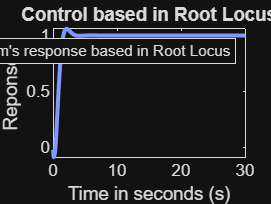

t_rl_act3_d4 = 0:0.1:30;
[y_rl_act3_d4, t_rl_sim_act3_d4] = step(sys_controlled_act3_d4_rl, t_rl_act3_d4);
figure;
plot(t_rl_sim_act3_d4, y_rl_act3_d4, "LineWidth", 2, "Color", [0.5 0.6 1])
title("Control based in Root Locus")
legend("System's response based in Root Locus")
xlabel("Time in seconds (s)")
ylabel("Reponse")

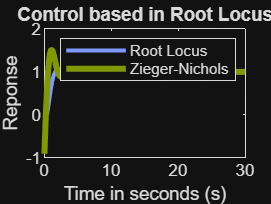


%Inciso 4. Comparación de resultados
figure;
plot(t_rl_sim_act3_d4, y_rl_act3_d4, "LineWidth", 2, "Color", [0.5 0.6 1])
hold on;
plot(t_c_sys_zn,y_zn_act3_d4, "LineWidth", 3, "Color", [0.5 0.6 0])
title("Control based in Root Locus")
legend("Root Locus", "Zieger-Nichols")
xlabel("Time in seconds (s)")
ylabel("Reponse")
hold off;

**DIA 5**

Este día nos concetramos en realizar actividades relaconadas con los diagramas de Bode

Análisis de Estabilidad y Diseño en Frecuencia para el Control de Velocidad de un Top Drive (Oil & Gas)Contexto Industrial

El sistema de rotación superior (*Top Drive*) en una plataforma de perforación petrolera es el encargado de girar la sarta de perforación y la broca. Mantener un control preciso de la velocidad angular del *Top Drive* es crítico para optimizar la Tasa de Penetración (ROP) y prevenir fallas catastróficas por torsión (como el fenómeno de *stick-slip*). La dinámica electromecánica del motor del *Top Drive* en lazo abierto se modela como un sistema de primer orden, cuya función de transferencia relaciona la acción de control de voltaje U(s) con la velocidad de rotación medida en RPM Y(s):


$$G\left(s\right)=\frac{\;K_m }{\tau_m s+1}$$


Donde los parámetros nominales de la planta son una constante de ganancia del motor $K_m =12$ y una constante de tiempo del sistema $\tau_{m\;} =0\ldotp 8\;s$.

Requerimientos del Problema

Para asegurar un comportamiento robusto ante las perturbaciones del subsuelo, se implementará un controlador Proporcional-Integral (PI) con la estructura:


$$G_c \left(s\right)=K_p \left(1+\frac{\;1}{T_i s}\right)=\frac{\;K_p \left(T_i s+1\right)}{T_i s}$$


Utilizando las herramientas de análisis en frecuencia de **MATLAB**, resuelva los siguientes incisos:

- **Modelado y Respuesta en Lazo Abierto:** Defina la función de transferencia de la planta G(s). Grafique el diagrama de Bode del sistema sin controlar utilizando una ganancia unitaria provisional K=1 y analice el comportamiento de la magnitud y la fase.

- **Búsqueda del Límite de Estabilidad:** Determine analíticamente y mediante software si existe una ganancia crítica $K_{\mathrm{cr}}$ máxima puramente proporcional antes de que el sistema en lazo cerrado se vuelva inestable. Justifique su respuesta basándose en el Margen de Ganancia (GM) y Margen de Fase (PM).

- **Diseño del Controlador PI por Criterio de Margen de Fase:** Diseñe las constantes $K_p$ y $T_i$ del controlador PI para satisfacer los siguientes criterios de robustez en lazo abierto:

- **Margen de Fase (****PM****):** $\ge 45\degree$

- **Margen de Ganancia (****GM):** $\ge 6\mathrm{dB}$

- *Pauta de diseño:* Para asegurar una buena acción integral, configure el tiempo integral $T_i$ de modo que el cero del controlador cancele el polo de la planta, o ubique la frecuencia de cruce de ganancia ($\omega_c$) en un punto que balancee rapidez y estabilidad.

- **Validación del Desempeño:** Grafique en una misma figura el diagrama de Bode del sistema en lazo abierto original frente al sistema con el controlador PI diseñado. Use comandos de MATLAB para etiquetar automáticamente los márgenes de estabilidad obtenidos y verifique el cumplimiento estricto de las especificaciones.

Desarrollo:

%Inciso 1.
k_act1_d5 = 12;
tau_act1_d5 = 0.8;
num_act1_d5 = [k_act1_d5];
den_act1_d5 = [tau_act1_d5 1];
tf_act1_d5 = tf(num_act1_d5, den_act1_d5)


tf_act1_d5 =
 
     12
  ---------
  0.8 s + 1
 
Continuous-time transfer function.


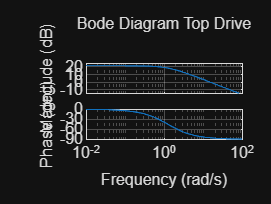

figure;
opts = bodeoptions;
%opts.FreqUnits = 'Hz'; % Cambia el eje X a Hertz
opts.Grid = 'on';      % Fuerza que se vea la cuadrícula
%bode(sys, opts)
bode(tf_act1_d5, opts)
title("Bode Diagram Top Drive")

figure;
[GM, PM, w_cg, w_cp] = margin(tf_act1_d5)

GM = Inf

PM = 94.7802

w_cg = NaN

w_cp = 14.9478

GM_real = 20*log10(GM)

GM_real = Inf

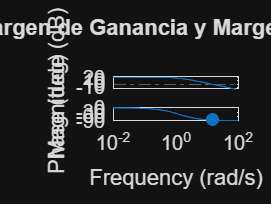

%GM margende ganancia absoluto, toca convertirlo
%PM: Margen de fase directo en grados
%w_cg frecuencia de crice de fase
%w_cp frecuencia de cruce de ganancia
margin(tf_act1_d5)
title("Margen de Ganancia y Margen de Fase")



%Incicso 3:
%Para hacer la planta más senscilla, ponemos T_i = 0.8 para que coincida
%con el el denominador de la planta
%Se elige 15 rad/s como un compromiso entre velocidad y rechazo al ruido
w_cp_desired = 15; 
% Calculamos la ganancia integral (Ki) basada en la relación Ki = Kp / Ti.
% Como Ti = tau = 0.8 para la cancelación, dividimos Kp entre la constante de tiempo.
kp = w_cp_desired/(k_act1_d5/ tau_act1_d5)

kp = 1

ki = kp/tau_act1_d5

ki = 1.2500

controller_act1_d5 = pid(kp, ki, 0)


controller_act1_d5 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1, Ki = 1.25
 
Continuous-time PI controller in parallel form.


sys_act1_d5_wc = feedback(controller_act1_d5 * tf_act1_d5, 1)


sys_act1_d5_wc =
 
       12 s + 15
  -------------------
  0.8 s^2 + 13 s + 15
 
Continuous-time transfer function.


t_asim_act1_d5 = 0:0.001:1.5;
info_top_drive = stepinfo(sys_act1_d5_wc)

info_top_drive = struct with fields:
         RiseTime: 0.1465
    TransientTime: 0.2608
     SettlingTime: 0.2608
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.4881


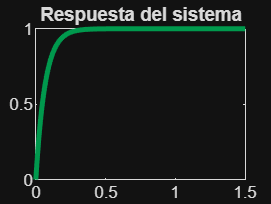

[y_act1_d5, t_act1_d5] = step(sys_act1_d5_wc, t_asim_act1_d5);
figure;
plot(t_act1_d5, y_act1_d5, 'LineWidth', 2.5, 'Color', [0 0.6 0.3])
title("Respuesta del sistema")

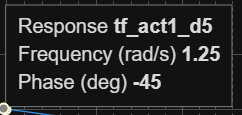

Actividad 2:

Análisis de Estabilidad y Desempeño Transitorio en el Control de Azimut de una Antena Satelital

Este ejrcicio fue extraído del capítulo 10 de los *Case Study* del libro de Norman Nise.

Contexto Industrial:

Las antenas de seguimiento satelital y los sistemas de radar requieren apuntar con una precisión milimétrica en sus ejes de elevación y azimut (giro horizontal). El sistema de posicionamiento está compuesto por un preamplificador con ganancia ajustable K, un amplificador de potencia, un motor de corriente continua y un tren de engranajes.

Cuando el sistema opera en lazo abierto (Configuración 1) con una ganancia de preamplificación unitaria K=1, la función de transferencia global del lazo (que incluye la planta y los sensores de retroalimentación) está dada por:


$$G\left(s\right)H\left(s\right)=\frac{6\ldotp 63K}{s\left(s+1\ldotp 71\right)\left(s+100\right)}$$


**Enunciado y Tareas:** Utilice diagramas de Bode para realizar el siguiente análisis de estabilidad y diseño:

- **Trazado de Bode:** Dibuje las gráficas de magnitud en dB y fase en grados para una ganancia unitaria (*K*=1).

- **Rango de Estabilidad:** Encuentre analíticamente y mediante MATLAB el rango de ganancia del preamplificador (*K*) necesario para mantener la estabilidad del sistema en lazo cerrado.

- **Márgenes de Estabilidad:** Para una ganancia específica (ej. *K*=30), determine el **Margen de Ganancia (***GM***)**, el **Margen de Fase (***PM***)** y las frecuencias de cruce correspondientes ($\omega_{\mathrm{GM}}$ y $\omega_{\mathrm{PM}} \;$).

- **Predicción Transitoria:** A partir del Margen de Fase, calcule el sobreimpulso esperado y estime el tiempo de asentamiento ($T_s$) y tiempo de pico ($T_p$) utilizando el ancho de banda del sistema (*B**W*).

%Inciso 1
num_act2_d5 = [6.63];
den_act2_d5 = [1 101.71 171 0];
num_tf_act2_d5 = num_act2_d5;
den_tf_act2_d5 =  den_act2_d5;
tf_sys_act2_d5 = tf(num_tf_act2_d5, den_tf_act2_d5)


tf_sys_act2_d5 =
 
           6.63
  -----------------------
  s^3 + 101.7 s^2 + 171 s
 
Continuous-time transfer function.


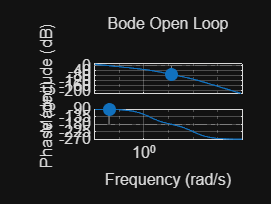

opts_act2_d5 = bodeoptions;
opts_act2_d5.Grid = "on";
figure;
margin(tf_sys_act2_d5, opts_act2_d5)
title("Bode Open Loop")

%Información del sistema
[GM_act2_d5, PM_act2_d5, w_cg_act2_d5 ,w_cp_act2_d5] = margin(tf_sys_act2_d5)

GM_act2_d5 = 2.6233e+03

PM_act2_d5 = 88.6793

w_cg_act2_d5 = 13.0767

w_cp_act2_d5 = 0.0388


%Inciso 2
%Con GM_act2_d5 ya calculamos la gananacia crítica, pero lo haremos de
%forma analítica para este inciso
%Primero debemos calcular la frecuencia de cruce de fase
syms x
ang_total_sys_act2_d5 = -180 ==  0 - 90 - atand(x/1.71) - atand(x/100)

$$ang\_total\_sys\_act2\_d5 = -180=-\frac{180\,\mathrm{atan}\left(\frac{x}{100}\right)}{\pi }-\frac{180\,\mathrm{atan}\left(\frac{100\,x}{171}\right)}{\pi }-90$$

w_gm_act2_d5 = solve(ang_total_sys_act2_d5, x);
w_gm_act2_d5_analitica = double(w_gm_act2_d5(1)) %el (1) es para escoger uno solo de los valores de matlab

w_gm_act2_d5_analitica = 13.0767

%Calculamos la ganacia crítica:
% |Kcr*G(jw)*H(jw)|=1
syms Kcr
Kcr_act2_d5 = 1 == Kcr*(6.63/(sqrt(w_gm_act2_d5_analitica^2) * sqrt(w_gm_act2_d5_analitica^2 + 1.71^2) * sqrt(w_gm_act2_d5_analitica^2 + 100^2)))

$$Kcr\_act2\_d5 = 1=\frac{878989119454221\,\mathrm{Kcr}}{2305843009213693952}$$

Kcr_act2_d5_sym = solve(Kcr_act2_d5, Kcr)

$$Kcr\_act2\_d5\_sym = \frac{2305843009213693952}{878989119454221}$$

Kcr_act2_d5_sym_analitic = double(Kcr_act2_d5_sym)

Kcr_act2_d5_sym_analitic = 2.6233e+03

%Verificamos así el resultado de la función Margin

Por ello K debe cumplir con 0 < K < `2.6233 * 10^3.`

%Inciso 3.
num_tf_act2_d5 = 30 * num_act2_d5;
tf_sys_act2_d5 = tf(num_tf_act2_d5, den_tf_act2_d5)


tf_sys_act2_d5 =
 
           198.9
  -----------------------
  s^3 + 101.7 s^2 + 171 s
 
Continuous-time transfer function.


[GM_act2_d5, PM_act2_d5, w_cg_act2_d5 ,w_cp_act2_d5] = margin(tf_sys_act2_d5)

GM_act2_d5 = 87.4430

PM_act2_d5 = 59.0266

w_cg_act2_d5 = 13.0767

w_cp_act2_d5 = 1.0032


margen_de_ganancia = 20*log10(GM_act2_d5)

margen_de_ganancia = 38.8345

Con ello obtenemos que:

- Margen de ganacia: 38.8345 dB

- Margen de Fase: `59.0266 `

- Frecuencia de cruce de ganancia:  `1.0032 rad/s`

- Frecuencia de cruce de fase: `13.0767 rad/s `

%Inciso 4.
%con la aproximacion de
%zeta = PM/100
zeta_act2_d5 = PM_act2_d5/100

zeta_act2_d5 = 0.5903

overshoot_act2_d5 = exp(-(zeta_act2_d5 * pi/ sqrt(1 - (zeta_act2_d5)^2)))*100

overshoot_act2_d5 = 10.0533

%Aproximamos BW a W_pm
BW = w_cp_act2_d5

BW = 1.0032

%Usamos la relacio´n entre BW y wn
nat_freq_act2_d5 = BW/(sqrt((1-2*zeta_act2_d5^2) + sqrt(4*zeta_act2_d5^4 - 4*zeta_act2_d5^2 + 2)))

nat_freq_act2_d5 = 0.8640


Tp_act2_d5 = pi/(nat_freq_act2_d5 *sqrt(1- zeta_act2_d5^2))

Tp_act2_d5 = 4.5045

Ts_act2_d5 = 4/(zeta_act2_d5 * nat_freq_act2_d5)

Ts_act2_d5 = 7.8432

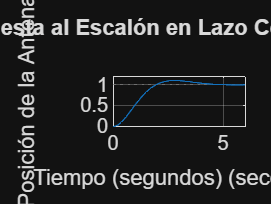

sys_cl_act2_d5 = feedback(tf_sys_act2_d5, 1);


figure;
step(sys_cl_act2_d5);
grid on;
title('Respuesta al Escalón en Lazo Cerrado (K = 30)');
xlabel('Tiempo (segundos)');
ylabel('Posición de la Antena');

A través del modelado simbólico de la fase del sistema, se determinó de forma analítica que la ganancia crítica del preamplificador es $K_{\mathrm{cr}}$ = 2623.3. Esto establece un límite estricto de operación 0 < K < 2623.3. Cualquier ganancia igual o superior a este valor provocará que el sistema de la antena entre en una oscilación destructiva e inestable.

Al evaluar el sistema en su condición nominal de K = 30, se obtuvo un Margen de Ganancia de 38.83 dB y un Margen de Fase de 59.02°. Estos valores demuestran que el sistema es altamente robusto frente a perturbaciones externas o variaciones en los componentes, operando con un colchón de seguridad muy amplio respecto al límite de inestabilidad.